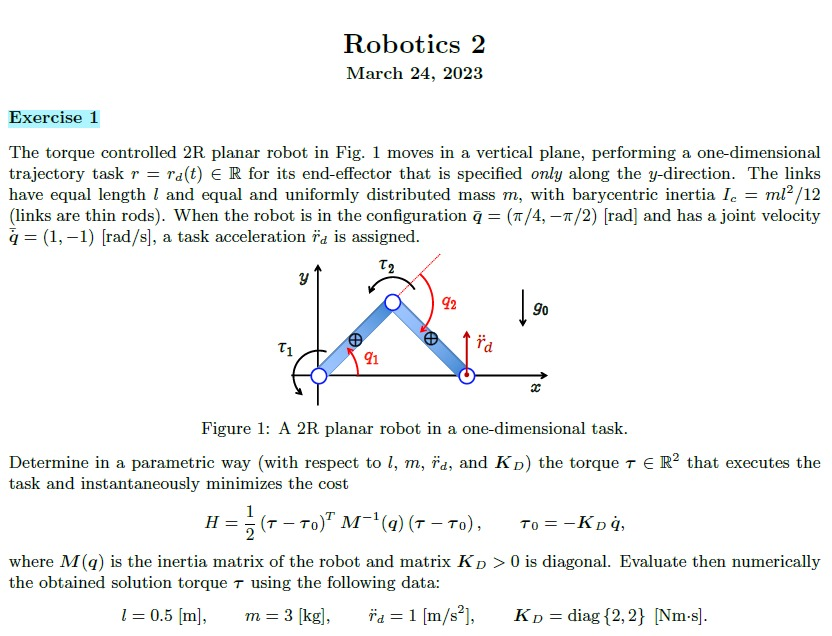

clc;
clear;

%% -------- Symbolic Variables --------
syms q1 q2 dq1 dq2 real
syms l m g0 r_ddot real
syms kd1 kd2 real

q  = [q1; q2];
dq = [dq1; dq2];
KD = diag([kd1, kd2]);
tau_0 = -KD * dq;

%% -------- End-effector y-Position (task) --------
y = l*sin(q1) + l*sin(q1 + q2);       % Only y-direction
J = jacobian(y, q);                   % dy/dq → 1x2
dJ = diff(J, q1)*dq1 + diff(J, q2)*dq2; % scalar

%% -------- Inertia Matrix via Kinetic Energy --------
Ic = m*l^2/12;

% COM positions
x1 = l/2 * cos(q1);  y1 = l/2 * sin(q1);
x2 = l*cos(q1) + l/2*cos(q1+q2);
y2 = l*sin(q1) + l/2*sin(q1+q2);

% Velocities
vx1 = diff(x1,q1)*dq1 + diff(x1,q2)*dq2;
vy1 = diff(y1,q1)*dq1 + diff(y1,q2)*dq2;
vx2 = diff(x2,q1)*dq1 + diff(x2,q2)*dq2;
vy2 = diff(y2,q1)*dq1 + diff(y2,q2)*dq2;

% Kinetic Energy
T1 = simplify(0.5*m*[vx1 vy1]*[vx1; vy1;] + 0.5*Ic*dq1^2)

$$T1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,l^{2}\,m}{6}$$

T2 = simplify(0.5*m*[vx2 vy2]*[vx2; vy2;] + 0.5*Ic*(dq1 + dq2)^2)

$$T2 = \frac{l^{2}\,m\,\left(2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}+4\,{{\mathrm{dq}}_{1}}^{2}+{{\mathrm{dq}}_{2}}^{2}+3\,{{\mathrm{dq}}_{1}}^{2}\,\cos\left(q_{2}\right)+3\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\right)}{6}$$

T = simplify(T1 + T2);

% Inertia matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, 'Steps', 100)

$$M = \left(\begin{array}{cc} \frac{l^{2}\,m\,\left(3\,\cos\left(q_{2}\right)+5\right)}{3} & \frac{l^{2}\,m\,\left(3\,\cos\left(q_{2}\right)+2\right)}{6}\\ \frac{l^{2}\,m\,\left(3\,\cos\left(q_{2}\right)+2\right)}{6} & \frac{l^{2}\,m}{3} \end{array}\right)$$


%% -------- Gravity vector --------
g0 = 9.81;
U = m*g0*(l/2*sin(q1) + l*sin(q1) + l/2*sin(q1 + q2));
g_q = simplify([diff(U,q1); diff(U,q2)])

$$g\_q = \left(\begin{array}{c} \frac{981\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+3\,\cos\left(q_{1}\right)\right)}{200}\\ \frac{981\,l\,m\,\cos\left(q_{1}+q_{2}\right)}{200} \end{array}\right)$$


%% -------- Coriolis matrix (Christoffel symbols) --------
q = [q1; q2];
dq = [dq1; dq2];
C = sym(zeros(2,2));
for i = 1:2
    for j = 1:2
        temp = 0;
        for k = 1:2
            temp = temp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(temp);
    end
end
c_q = simplify(C * dq)  % centrifugal + Coriolis vector

$$c\_q = \left(\begin{array}{c} -\frac{{\mathrm{dq}}_{2}\,l^{2}\,m\,\sin\left(q_{2}\right)\,\left(2\,{\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}{2}\\ \frac{{{\mathrm{dq}}_{1}}^{2}\,l^{2}\,m\,\sin\left(q_{2}\right)}{2} \end{array}\right)$$

n_q = simplify(c_q + g_q);

%% -------- Final torque (correct minimum H solution) --------
Minv = simplify(inv(M));
JMJt = simplify(J * Minv * J.');           % scalar (1x1)
JMJt_inv = simplify(inv(JMJt));            % scalar

% Step 2: main expression with J^T leading term
term_1 = J.' * JMJt_inv * (r_ddot - dJ + J * Minv * n_q);
term_2 = (eye(2) - J.' * JMJt_inv * J * Minv) * tau_0;
tau = simplify(term_1 + term_2);

%% -------- Numerical Evaluation --------
l_val = 0.5;
m_val = 3;
q_val = [pi/4; -pi/2];
dq_val = [1; -1];
rdd_val = 1;
kd_val = [2; 2];

tau_num = double(subs(tau, [q1, q2, dq1, dq2, l, m, r_ddot, kd1, kd2], [pi/4, -pi/2, 1, -1, 0.5, 3, 1, 2, 2]));

%% -------- Display Result --------
disp("Minimum-torque solution τ that minimizes H:");

Minimum-torque solution τ that minimizes H:


disp(tau_num);

   11.8985   11.4985
    8.9492    8.7492

